# Pulse Code Modulation (PCM)

% Author Name : Atmanand Manoj Gauns
% Affiliation : Roll No.: 201104012
%               Branch : E&TC GCE
%               Year : TE Sem- 5 2021-22 

### Variables


clc;
clear;
fm =2; % message frequency
fs = 200*fm; % sampling frequency
t=0:1/fs:2; % time index
l=length(t);
i=(-l/2:1:l/2-1); %% frequency series index
Vm=2;

##                                          Sending End

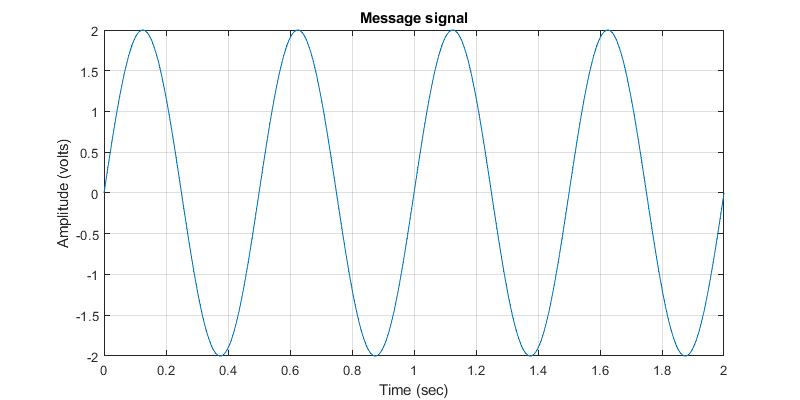

% Message Signal
v_m=Vm*sin(2*pi*fm*t);
f0=figure;
plot(t,v_m);
xlabel('Time (sec)');
ylabel('Amplitude (volts)');
title('Message signal');
set(f0,'Position',[0 0 800 400]);
grid on;


% Shited Message Singal
v_m_shifted=v_m+Vm;

### Quantizing

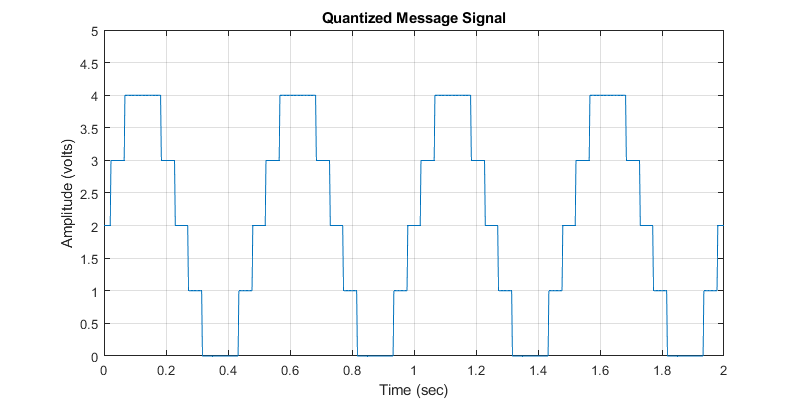

v_m_quantized=round(v_m_shifted);
plot(t,v_m_quantized);
xlabel('Time (sec)');
ylabel('Amplitude (volts)');
title('Quantized Message Signal');
set(f0,'Position',[0 0 800 400]);
grid on;

ylim([0.00 5.00])

### Encoding

v_m_encoded=dec2bin(v_m_quantized);

##                                        Receiving End

###  Decoding

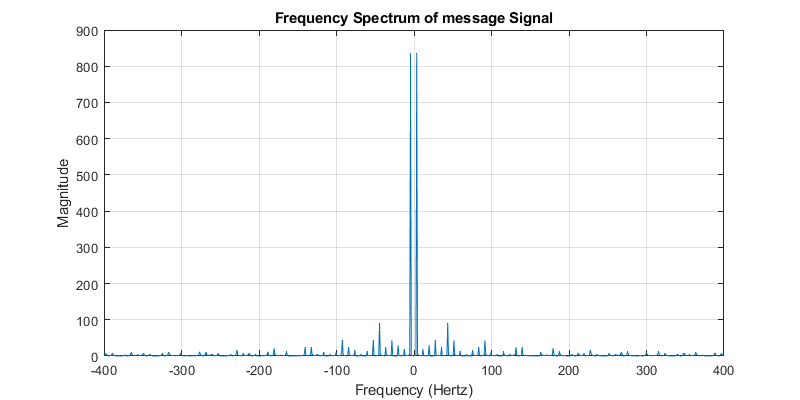

v_m_decoded= bin2dec(v_m_encoded);

%% Reconstructing
v_m_reconstructed=v_m_decoded-Vm;

% In frequency Spectrum of Reconstructed
spec_vm_rec=(fftshift(fft(v_m_reconstructed)));
plot(i,(abs(spec_vm_rec)));
xlabel('Frequency (Hertz)');
ylabel('Magnitude');
title('Frequency Spectrum of message Signal');
set(f0,'Position',[0 0 800 400]);
grid on;

xlim([-400 400])


% Low Pass Filter
l=length(spec_vm_rec);
b=10;
a=round(l/2);
lpf=[zeros(1,a-b),ones(1,2*b),zeros(1,l-(b+a))];
Fout=transpose(spec_vm_rec).*lpf;
figure(1);
plot(i,lpf*2);hold on
plot(i,Fout/8);

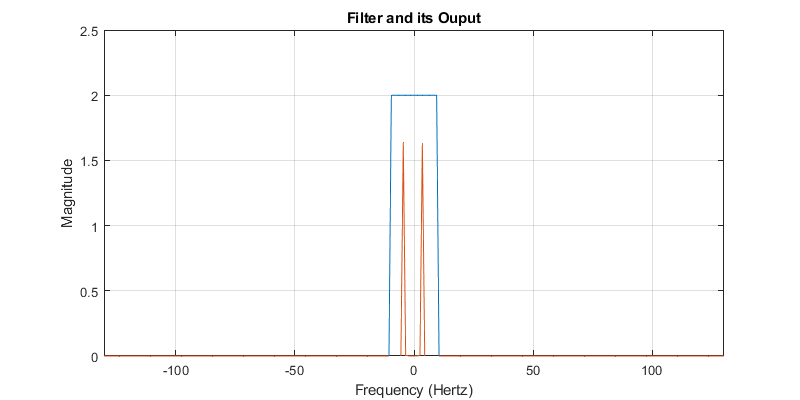

xlabel('Frequency (Hertz)');
ylabel('Magnitude');
title('Filter and its Ouput');
set(f0,'Position',[0 0 800 400]);
grid on;

xlim([-130 130])
ylim([0 2.5])



% v_m_recovered=ifft((Vft));
v_m_recovered=ifft(ifftshift(Fout));
f2=figure;
plot(t,v_m);hold on  % Original Signal - blue
plot(t,(v_m_recovered -2));      % Recovered Signal - orange

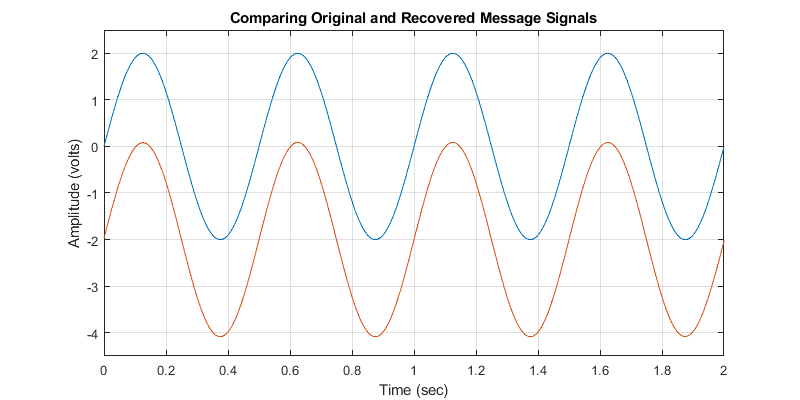

xlabel('Time (sec)');
ylabel('Amplitude (volts)');
title('Comparing Original and Recovered Message Signals') ;
set(f2,'Position',[0 0 800 400]);
grid on;

ylim([-4.5 2.5])